addpath('Shapes')
load("Data\CFD_confined_TSR_1_1.mat")
%load("Data\CFD_confined_LES_TSR_1_9.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
thetab = 365 - theta;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
thet = [0:pi/32:2*pi,0]';
rt = 2.042;
Uinf = 0.91;
lam = 1.1;
%lam = 1.9;
Omega = lam*Uinf/rt;
GC = struct;
GC.alphaP = 6;
GC.lambda = lam;
Urels = struct;
num = length(theta)

num = 62

Rqcs = [-1.65 -1.85 -2.05 -2.25 -2.45;0 0 0 0 0];
Rqcs = [Rqcs(1,:);Rqcs(2,:)+2.042];
dThetas = zeros(1,length(Rqcs),num);
rbvs = zeros(2,length(Rqcs),num);
bvs = zeros(2,1,num);
Us = struct;

tic
for k = 1:num%length(theta)
alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X);
Xrot3 = zeros(sz);
Yrot3 = zeros(sz);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alpha);
    Xrot3(:,j) = res(1,:);
    Yrot3(:,j) = res(2,:);
end
foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest(:,:) = res';
%qc = 2.118*[sind(theta(k));cosd(theta(k))];
qc = 2.042*[sind(theta(k));cosd(theta(k))];
qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc);

radius = [1.6 1.7 1.8 1.9 2]./2;
%radius = [1.6 1.7]./2;
sizes = [1 1.3 1.6 1.9 2.2];
Cin = zeros(length(X),length(X),length(radius));
Ca = zeros(66,2,length(radius));
for i = 1:length(radius)
    [Cin(:,:,i),Ca(:,:,i)] = Circle2(qc,radius(i),Xrot3,Yrot3);
end
Rin2 = zeros(length(X),length(X),length(Rqcs));
Ra2 = zeros(5,2,length(Rqcs));
for i = 1:length(Rqcs)
    [Rin2(:,:,i),Ra2(:,:,i)] = Rect2(Rqcs(:,i),0.1,2,Xrot3,Yrot3);
end

%[Pin, Pa] = Points(theta,1,1,rt,X,Y);
[Pin, Pa] = Points2(qc,1,0.5,Xrot3,Yrot3);
%need to investigate making a Points2.m to meet 
% standards of other methods. Points.m derives
% the quarter chord (qc) from inputs, may be 
% better to just give qc point.
%Also in need of investigation is the m and 
% n parameters of Points.m

%[Cin,Ca] = Circle2(qc,1,Xrot3,Yrot3);
qc(1) = qc(1)-1;
[Rin,Ra] = Rect2(qc,0.25,2,Xrot3,Yrot3);
foiltest2 = plot_foil(theta(k),1.5);
XYRy2 = Ry2*foiltest2';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';
Bin = inpolygon(Xrot3,Yrot3,foiltest2(:,1),foiltest2(:,2));



u3 = zeros(sz);
v3 = zeros(sz);
for i = 1:sz
    for j = 1:sz
        XYRy2 = Ry2*[U(i,j);V(i,j)];
        res = subs(XYRy2,t,alpha);
        u3(i,j) = res(1);
        v3(i,j) = res(2);
    end
end

u4 = zeros(length(u3));
v4 = u4;
for i = 1:length(Xrot3)
    for j = 1:length(Xrot3)
        x = Xrot3(i,j);
        y = Yrot3(i,j);
        rRef = hypot(x,y);
        pv = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
        u4(i,j) = u3(i,j)+pv(1);
        v4(i,j) = v3(i,j)+pv(2);
    end
end

for i = 1:length(radius)
    Umeans.Circle(i) = mean(u4(logical(Cin(:,:,i))));
    Umeans.Rec(i) = mean(u4(logical(Rin2(:,:,i))));
end
Umeans.Point = mean(u4(logical(Pin)));
Vmeans.Point = mean(v4(logical(Pin)));
%this needs adjusting bc rn it averages both points 
% and I don't want to do that yet?


for i = 1:length(radius)
    Vmeans.Circle(i) = mean(v4(logical(Cin(:,:,i))));
    Vmeans.Rec(i) = mean(v4(logical(Rin2(:,:,i))));
end

rbv = Rqcs*0;
for i = 1:length(Rqcs)
    rRef = hypot(Rqcs(1,i),Rqcs(2,i));
    rbv(:,i) = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
end

% for i = 1:2
%     rRefP = hypot(Pa(1,i),Pa(2,i));
%     pbv(:,i) = Omega*rRefP.*[-cosd(alpha);-sind(alpha)];
% end
%maybe if I separate out each pt but until then

rRefP = hypot(mean(Pa(1,:)),mean(Pa(2,:)));
pbv = Omega*rRefP.*[-cosd(alpha);-sind(alpha)];

rbvs(:,:,k) = rbv;

dThetas(:,:,k) = (Umeans.Rec(:,:)+rbv(1,:))./abs(Rqcs(1,:))*Omega;

bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
bvs(:,:,k) = bv;

Yrot4 = Yrot3-2.042;

% quiver(Xrot3,Yrot4,u4,v4)
% xlim([-2.5 1.5])
% ylim([-1.5 1.5])
% grid on
% hold on
% fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
% for i = 1:length(radius)
% quiver(0,0,Umeans.Circle(i)+bv(1),Vmeans.Circle(i)+bv(2),'LineWidth',2)
% end
% for i = 1:length(radius)
%     plot(Ca(:,1,i),Ca(:,2,i)-2.042)
% end
%plot(Ca(:,1),Ca(:,2))
%plot(Ra(:,1),Ra(:,2))
%plot(foiltest2(:,1),foiltest2(:,2),'k')
%hold off

%aoa testing
for i = 1:length(radius)
Urels(k).C(i,:) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
Urels(k).R(i,:) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
end
Urels(k).P = [Umeans.Point;Vmeans.Point]+pbv;
Us(k).u3 = u3;
Us(k).v3 = v3;
Us(k).u4 = u4;
Us(k).v4 = v4;
end
toc

Elapsed time is 5040.810309 seconds.


for k = 1:num
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    bvs(:,:,k) = bv;
end
bvs

bvs = bvs(:,:,1) =

   -1.0000
    0.0442


bvs(:,:,2) =

   -0.9992
   -0.0597


bvs(:,:,3) =

   -0.9876
   -0.1630


bvs(:,:,4) =

   -0.9654
   -0.2646


bvs(:,:,5) =

   -0.9328
   -0.3632


bvs(:,:,6) =

   -0.8901
   -0.4580


bvs(:,:,7) =

   -0.8378
   -0.5478


bvs(:,:,8) =

   -0.7765
   -0.6317


bvs(:,:,9) =

   -0.7068
   -0.7089


bvs(:,:,10) =

   -0.6295
   -0.7783


bvs(:,:,11) =

   -0.5454
   -0.8394


bvs(:,:,12) =

   -0.4554
   -0.8914


bvs(:,:,13) =

   -0.3605
   -0.9338


bvs(:,:,14) =

   -0.2617
   -0.9662


bvs(:,:,15) =

   -0.1601
   -0.9881


bvs(:,:,16) =

   -0.0568
   -0.9994


bvs(:,:,17) =

    0.0471
   -0.9999


bvs(:,:,18) =

    0.1506
   -0.9896


bvs(:,:,19) =

    0.2524
   -0.9687


bvs(:,:,20) =

    0.3515
   -0.9373


bvs(:,:,21) =

    0.4468
   -0.8958


bvs(:,:,22) =

    0.5372
   -0.8446


bvs(:,:,23) =

    0.6219
   -0.7844


bvs(:,:,24) =

    0.6999
   -0.7156


bvs(:,:,25) =

    0.7703
   -0.6392


bvs(:,:,26) =

    0.8325
  

% tic
% for b = 1:62
% for i = 1:length(radius)
% Urels(k).C(i,:) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
% Urels(k).R(i,:) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
% end
% end
% toc

% banan = zeros(length(radius),2,k,2);
% tic
% for b = 1:62
% for i = 1:length(radius)
% banan(i,:,k,1) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
% banan(i,:,k,2) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
% end
% end
% toc

test2 = [Umeans.Circle(1);Vmeans.Circle(1)]+bv

test2 =    -1.2201
    0.0505


hypot(test2(1),test2(2))

ans = 1.2211

addpath("Subfunctions")
AOA(-bv,Urels(1).C(1,:)',theta(1),GC)

ans = -4.1548

alpha

alpha = 360.5345

% for i =1:length(theta)
%     
% end

%duder = zeros(length(theta),1)
duder = zeros(num,1)

duder =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


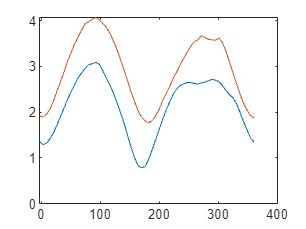

for i =1:num%length(theta)
duder(i) = hypot(Urels(i).C(1),Urels(i).C(1,2))/Uinf;
end
plot(theta(1:num),duder)
hold on
duder3 = zeros(num,1);
for i =1:num%length(theta)
duder3(i) = hypot(Urels(i).R(1),Urels(i).R(1,2))/Uinf;
end
plot(theta(1:num),duder3)
hold off

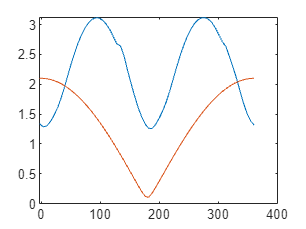

duder5 = zeros(num,1);
for i =1:num%length(theta)
duder5(i) = hypot(Urels(i).P(1),Urels(i).P(2))/Uinf;
end
plot(theta(1:num),duder5)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off

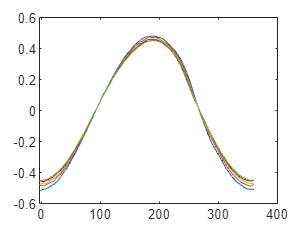

for i =1:num
    dt(i) = dThetas(:,1,i);
end
plot(theta,dt)
hold on
for j =2:5
    for i =1:num
    dt(i) = dThetas(:,j,i);
    end
plot(theta,dt)
end
hold off

duder*Uinf^2

ans =     1.1195
    1.0704
    1.0966
    1.1772
    1.2912
    1.4343
    1.5863
    1.7383
    1.8933
    2.0264


%duder2 = zeros(length(theta),1)
duder2 = zeros(num,1)

duder2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


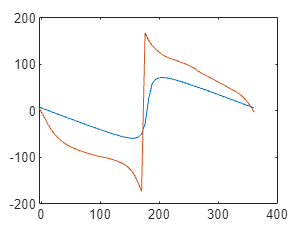

for i = 1:num%length(theta)
    [duder2(i,1),duder2(i,2)] = AOA(-bvs(:,:,i),Urels(i).C(4,:)',theta(i),GC);
end
plot(theta(1:num),duder2(:,2),theta(1:num),-duder2(:,1))

% don't forget if it throws an error, just try adding path

duder6 = zeros(num,1);
duder10 = duder6

duder10 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


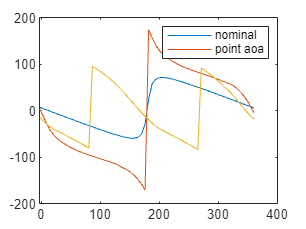

for i = 1:num%length(theta)
    %rRefP = hypot(mean(Pa(1,:)),mean(Pa(2,:)));
    pbv = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
    [duder6(i,1),duder6(i,2)] = AOA(-pbv,Urels(i).P,theta(i),GC);
    duder10(i,1) = atand(-(Urels(i).P(2)+pbv(1))/(Urels(i).P(1)+pbv(1)))+GC.alphaP;
end
plot(theta(1:num),duder6(:,2),theta(1:num),-duder6(:,1),theta(1:num),duder10)
legend('nominal','point aoa')

duder10

duder10 =   -14.3001
  -21.5930
  -28.6772
  -34.8839
  -39.7413
  -43.6898
  -47.4482
  -51.3338
  -55.3619
  -59.4312


ans = 1.6303

atand(-(Urels(1).P(1)-pbv(1))/(Urels(1).P(2)-pbv(2)))+GC.alphaP

ans = 44.8341

atand(-(Urels(1).P(2)+pbv(1))/(Urels(1).P(1)+pbv(1)))+GC.alphaP

ans = -14.3138

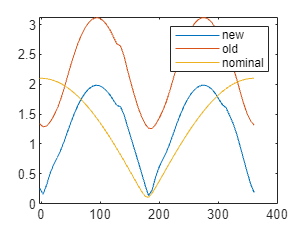

duder7 = zeros(num,1);
duder11 = duder7;
for i = 1:num
    pbv = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
    duder7(i) = hypot(Urels(i).P(1)-pbv(1),Urels(i).P(2)-pbv(2))/Uinf;
    duder11(i) = norm([Omega*rt+Urels(i).P(1)-pbv(1),Urels(i).P(2)-pbv(2)])/Uinf;
end
plot(theta(1:num),duder7)
hold on
plot(theta(1:num),duder5)
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
%plot(theta(1:num),duder11)
hold off
legend('new','old','nominal')

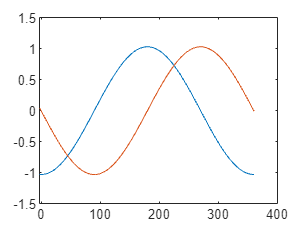

pbvs1 = zeros(num,2);
RelU = zeros(num,1);
RelV = RelU;
for i = 1:num
pbvs1(i,:) = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
RelU(i) = Urels(i).P(1);
RelV(i) = Urels(i).P(2);
end
plot(theta(1:num),pbvs1)

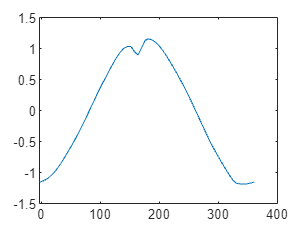

plot(theta(1:num),RelU)

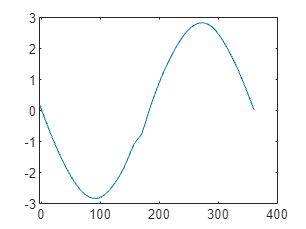

plot(theta(1:num),RelV)

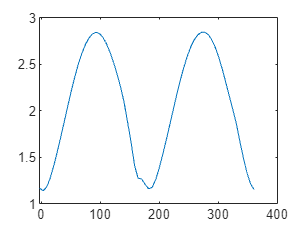

plot(theta(1:num),hypot(RelU,RelV))

hypot(Urels(num).P(1),Urels(num).P(2))/Uinf

ans = 1.2664

% making some figs for owen
Xrot5 = zeros(sz);
Yrot5 = zeros(sz);
h = 32

h = 32

alp = theta(h);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alp);
    Xrot5(:,j) = res(1,:);
    Yrot5(:,j) = res(2,:);
end
Yrot6 = Yrot5 - 2.042;

[Pin3,Pa3] = Points2([0;2.042],0.5,1,Xrot5,Yrot5);
[Cin3, Ca3] = Circle2([0;2.042],0.8,Xrot5,Yrot5);
rRefP = hypot(mean(Pa3(1,:)),mean(Pa3(2,:)));
pbv = Omega*rRefP.*[-cosd(alp);-sind(alp)];

for k = 1:num
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    bvs(:,:,k) = bv;
end

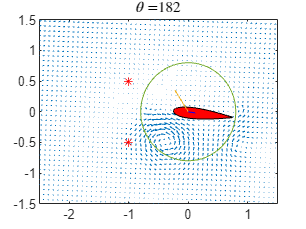

quiver(Xrot5,Yrot6,Us(h).u4,Us(h).v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
%quiver(0,0,Urels(h).P(1)-bvs(1,:,h),Urels(h).P(2)-bvs(2,:,h))
quiver(0,0,mean(Us(h).u3(logical(Pin3)))+bvs(1,:,h),mean(Us(h).v3(logical(Pin3)))+bvs(2,:,h),'b')
%quiver(0,0,mean(Us(h).u3(logical(Pin3)))+pbv(1),mean(Us(h).v3(logical(Pin3)))+pbv(2),'b')
quiver(0,0,mean(Us(h).u3(logical(Cin3)))+bvs(1,:,h),mean(Us(h).v3(logical(Cin3)))+bvs(2,:,h))
%quiver(0,0,mean(Us(h).u4(logical(Cin3))),mean(Us(h).v4(logical(Cin3))))
%quiver(0,0,mean(Us(h).u4(logical(Cin(:,:,5))))-bvs(1,:,h),mean(Us(h).v4(logical(Cin(:,:,5))))-bvs(2,:,h))
%quiver(0,0,Urels(h).C(5,1)-bvs(1,:,h),Urels(h).C(5,2)-bvs(2,:,h))
plot(Pa3(1,:),Pa3(2,:)-2.042,'*r')
plot(Ca3(:,1),Ca3(:,2)-2.042)
title('$\theta$ =182','Interpreter','latex')
hold off

theta(h)

ans = 181.9779

aT = [mean(Us(h).u4(logical(Pin3)))-bvs(1,:,h);mean(Us(h).v4(logical(Pin3)))-bvs(2,:,h)]

aT =    -0.8713
   -0.1227


[th,rh] = cart2pol(aT(1),aT(2))

th = -3.0017

rh = 0.8799

[xh,yh] = pol2cart(th+(6*pi/180),rh)

xh = -0.8537

yh = -0.2131

norm(Urels(num).P)/Uinf

ans = 1.2664

norm(Urels(1).P)/Uinf

ans = 1.2842


norm(Urels(num).P-pbvs1(num,:))/Uinf

ans = 1.3095

norm(Urels(1).P-pbvs1(1,:))/Uinf %these are done bc I had stopped adding pbv to it

ans = 1.4750

ur3 = zeros(num,1)

ur3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:num
    %ur3(i) = norm(Urels(i).P-pbvs1(i,:)+bvs(:,:,i));
    ur3(i) = norm(Urels(i).P+bvs(:,:,i));
end
ur3/Uinf

ans =     2.3801
    2.3505
    2.3836
    2.4692
    2.5926
    2.7411
    2.9077
    3.0878
    3.2755
    3.4627


ur2 = zeros(num,1)

ur2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:num
    ur2(i) = Urels(i).P(1);
end
ur2

ur2 =    -1.1533
   -1.1329
   -1.1043
   -1.0630
   -1.0064
   -0.9349
   -0.8523
   -0.7629
   -0.6695
   -0.5728


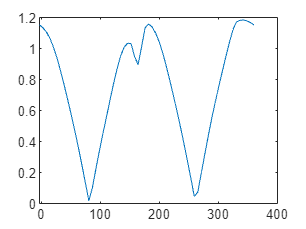

plot(theta(1:num),abs(ur2))

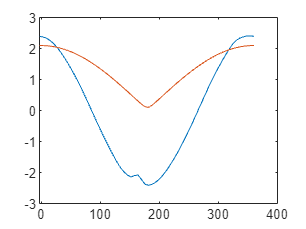

plot(theta(1:num),-(pbvs1(:,1)+RelU)/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off

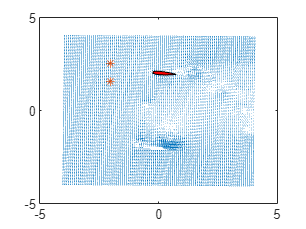

quiver(Xrot3,Yrot3,u3,v3)
[Pin2,Pa2] = Points2(qc,0.5,1,Xrot3,Yrot3);
% foiltest = plot_foil(theta(k),1);
% XYRy2 = Ry2*foiltest';
% res = subs(XYRy2,t,alpha);
% foiltest(:,:) = res';
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
plot(Pa2(1,:),Pa2(2,:),'*')
hold off

flowdata = flow_data;
x_center = zeros(num,1);
y_center = x_center;
u_fluid = x_center;
v_fluid = x_center;
for i = 1:num
    x_center(i) = rt*-sind(theta(i));
    y_center(i) = rt*cosd(theta(i));
    u_inter = griddedInterpolant(X,Y,flowdata(i).u);
    v_inter = griddedInterpolant(X,Y,flowdata(i).v);
    u_fluid(i) = circle_integral(x_center(i),y_center(i),1.6/2,u_inter);
    v_fluid(i) = circle_integral(x_center(i),y_center(i),1.6/2,v_inter);
end

bladeV = Omega*rt.*[-cosd(theta) sind(theta)]

bladeV =    -1.0000   -0.0442
   -0.9992    0.0597
   -0.9876    0.1630
   -0.9654    0.2646
   -0.9328    0.3632
   -0.8901    0.4580
   -0.8378    0.5478
   -0.7765    0.6317
   -0.7068    0.7089
   -0.6295    0.7783


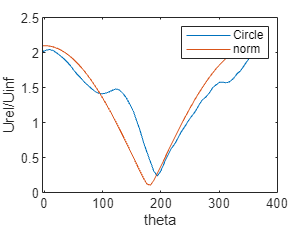

plot(theta(1:num),hypot(u_fluid-bladeV(:,1),v_fluid-bladeV(:,2))/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off
xlabel('theta')
ylabel('Urel/Uinf')
legend('Circle','norm')

[Uavg, Vavg] = avg_velocityfield(flowdata);
u_inter1 = griddedInterpolant(X,Y,Uavg);
v_inter1 = griddedInterpolant(X,Y,Vavg);
[u_fluid1, v_fluid1] = circleInt_whole(rt,1.6/2,theta,u_inter1,v_inter1);

bladeV = Omega*rt.*[-cosd(theta) sind(theta)]

bladeV =    -1.0000   -0.0442
   -0.9992    0.0597
   -0.9876    0.1630
   -0.9654    0.2646
   -0.9328    0.3632
   -0.8901    0.4580
   -0.8378    0.5478
   -0.7765    0.6317
   -0.7068    0.7089
   -0.6295    0.7783


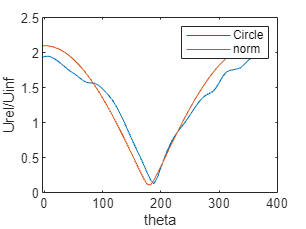

plot(theta(1:num),hypot(u_fluid1'-bladeV(:,1),v_fluid1'-bladeV(:,2))/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off
xlabel('theta')
ylabel('Urel/Uinf')
legend('Circle','norm')

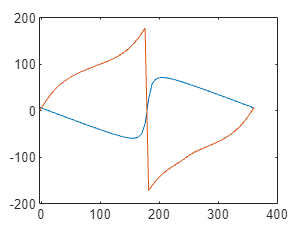

duder4 = zeros(num,1);
for i = 1:num%length(theta)
    [duder4(i,1),duder4(i,2)] = AOA(-rbvs(:,4,i),Urels(i).R(4,:)',theta(i),GC);
end
plot(theta(1:num),duder4(:,2),theta(1:num),duder4(:,1))

Urels(1).C(4,:)'

ans =    -1.2239
    0.2235


%Urels %figure out what I was doing here, looks partial